% 1. Go the simulation experiment folder

% give this simulation a name
SimulationName='Simulation_AfterRivisingFunctions_20231208';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/';
% create the simulation folder
cd(savefolder)
mkdir(SimulationName)

% go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/Simulation_AfterRivisingFunctions_20231208/'

cd(filepath)
mkdir('Simulated_data')

p1_samples=0.4:0.01:0.6; % simulate the p1 range
tau1=2.14; % tau1 
tau2=0.69; % tau2

afterpulse_ratio=0.0032; 

SS_samples=100000:50000:1000000; % simulated sample size range.

## Running fitting


global FixBackground FixedBackground

FixBackground = 0;

ch = 1; % only for FLIM channel 1
load('Prf_interp1.mat')
spc.fits{1}.prf = prf;
spc.datainfo.psPerUnit = (12.5/256)*1000;
spc.fits{1}.fitstart = 10*spc.datainfo.psPerUnit/1000;
spc.fits{1}.fitend = 235*spc.datainfo.psPerUnit/1000;

spc.fits{1}.beta2 = tau1; % p1 and p2 as 0.5
spc.fits{1}.beta4 = tau2;

sample_num = 500;

% fitting with no autofluorescence

for i = 1:length(p1_samples) % Running fitting from each p1 conditions

    % Load simulated sensor data from saved file with different p1 condition
    p1=p1_samples(i);
    simulated_name = ['Simulated_data_pooled/', num2str(p1), '_sensor.mat'];
    load(simulated_name)

    p1_fitted = zeros(sample_num, length(SS_samples));  % fitted p1
    tau_empTrunc = zeros(sample_num, length(SS_samples)); % lifetime calculated empirically based on fitting range. This will be the average lifetime I use
    fitting_parameters = {};


    for j = 1:length(SS_samples) % Under each sample size condition
        n_all = {};

        n_all{1} = n_sensor_simulated{j};

        SS = SS_samples(j);
       
        % Load simulated background data from saved file with different sample size condition
        bkgrd_simulated_name = ['Simulated_data_pooled/bkgrd_AP_',num2str(SS), '.mat'];
        load(bkgrd_simulated_name)

        n_all{2} = n_bkgrd_all;

        % Load simulated autofluorescence data from saved file with different sample size condition
        SS = SS_samples(j);
        autoF_simulated_name = ['Simulated_data_pooled/autoF_',num2str(SS), '.mat'];
        load(autoF_simulated_name)

        n_all{3} = n_auto_all;

        [p1_fitted_single, tau_empTrunc_single, fitting_parameters_single] = RunFitting(sample_num, n_all);
        p1_fitted(:,j) = p1_fitted_single;
        tau_empTrunc(:,j) = tau_empTrunc_single;
        fitting_parameters{j} = fitting_parameters_single;

    end

    % save the fitting parameters for each p1 conditon
    savename = ['Simulated_data_pooled/Results_20240311_', num2str(i), '.mat'];
    save(savename, 'p1_fitted','tau_empTrunc','fitting_parameters')

end

Error using load
Unable to find file or directory
'Simulated_data_pooled/0.4_sensor.mat'.


savename_postfix = 'Simulated_data_pooled/Results_20240311_'

savename_postfix = 'Simulated_data_pooled/Results_20240311_'

savename_postfix = '/Volumes/PcSSDA/Simulated_data/Results_20240328_NoBackground_'

savename_postfix = '/Volumes/PcSSDA/Simulated_data/Results_20240328_NoBackground_'

SS_samples=100000:50000:800000;

p1_mean_all = zeros(length(SS_samples), length(p1_samples));
p1_std_all = zeros(length(SS_samples), length(p1_samples));

tau_mean_all = zeros(length(SS_samples), length(p1_samples));
tau_std_all = zeros(length(SS_samples), length(p1_samples));

chi2_mean_all = zeros(length(SS_samples), length(p1_samples));
chi2_std_all = zeros(length(SS_samples), length(p1_samples));

for i = 1:length(p1_samples)
    p1=p1_samples(i);
    savename = [savename_postfix, num2str(i), '.mat']; 
    load(savename) % for each p1 condition, load the saved file, calculate the p1 and mean
    for j = 1:length(SS_samples)
        p1_mean_all(j,i) = mean(p1_fitted(:,j)); % mean p1
        p1_std_all(j,i) = std(p1_fitted(:,j)); % std p1

        tau_mean_all(j,i) = mean(tau_empTrunc(:,j)); % mean p1
        tau_std_all(j,i) = std(tau_empTrunc(:,j)); % std p1

        chi2_mean_all(j,i) = mean(fitting_parameters{j}{3}); % mean p1
        chi2_std_all(j,i) = std(fitting_parameters{j}{3}); % std p1

    end
end



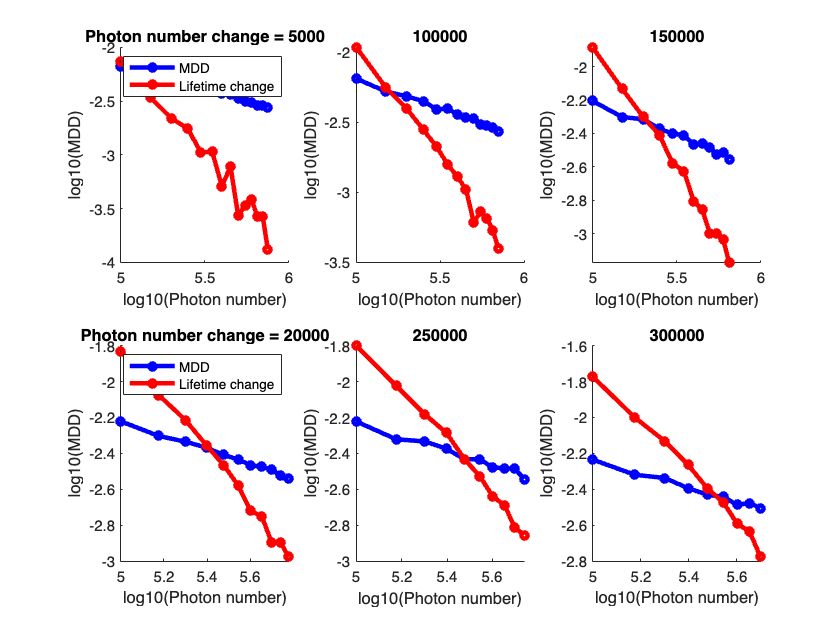

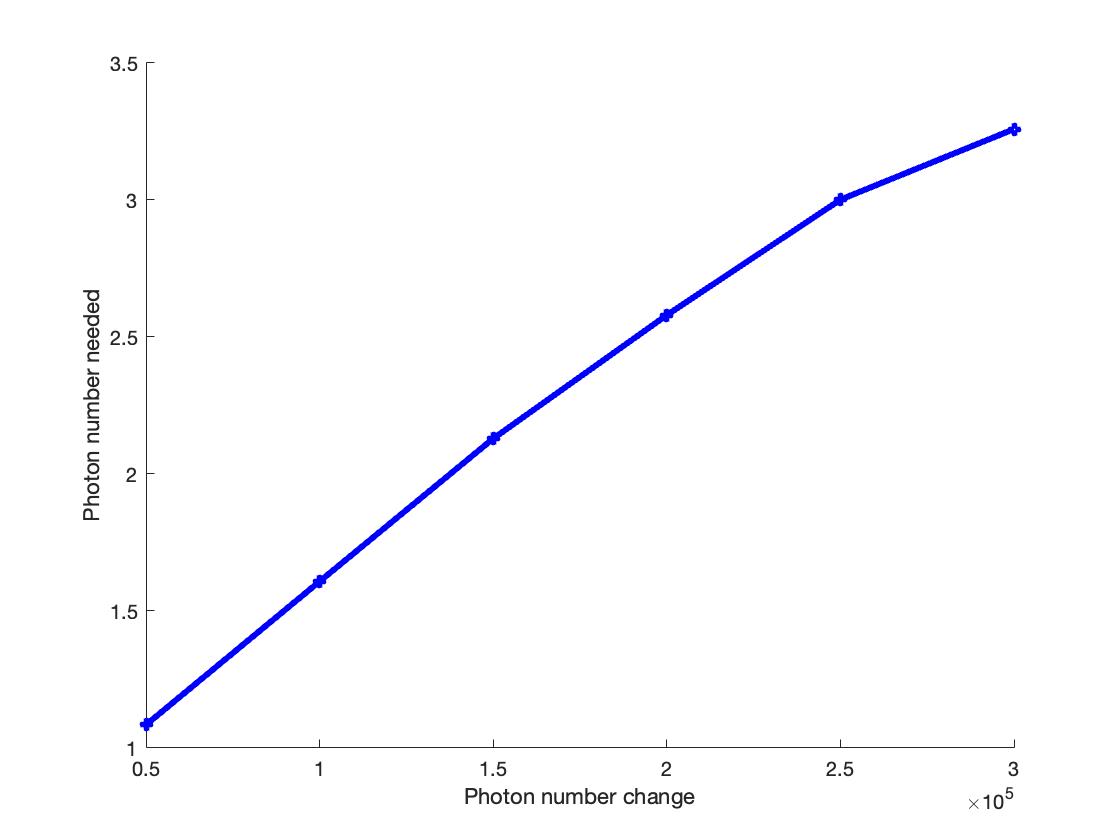


[p1_MDD_SS_all] = Calc_MDD(p1_samples, SS_samples, 5, 0.5, p1_std_all);
[changes_for_comparison_all, Minimum_photons_needed] = Calc_Minimum_Photons(p1_samples, SS_samples, p1_mean_all, p1_std_all, p1_MDD_SS_all);

% 2. Calculate the empirical lifetime of simulated final histograms with
% different p1 (0.4:0.01:0.6) and different sensor photon numbers
% (100000:50000:1000000) and save them in 'Tau_final_AllPhotons.mat'.

fit_range = [10 235]; % We use fitting range from 0.0489 to 11.5 ns for fitting and empirical lifetime calculation
x_axis = (1:1:(fit_range(2) - fit_range(1) + 1))*(12.5/256); % transform fitting range channels to lifetime

% define p1 and photon number range
p1_samples = 0.4:0.01:0.6;
SS_samples = 100000:50000:1000000;

tau_mean_all = zeros(length(SS_samples), length(p1_samples));
tau_std_all = zeros(length(SS_samples), length(p1_samples));

tau_all = {};

for i = 1:length(p1_samples)
    sensor_file_name = ['Simulated_data_pooled/', num2str(p1_samples(i)), '_sensor.mat'];
    load(sensor_file_name)

    for j = 1:length(SS_samples)

        autoF_file_name = ['Simulated_data_pooled/autoF_', num2str(SS_samples(j)), '.mat'];
        load(autoF_file_name)

        bkgrd_file_name = ['Simulated_data_pooled/bkgrd_AP_', num2str(SS_samples(j)), '.mat'];
        load(bkgrd_file_name)

        tau_sim = zeros(1, 500);

        for k = 1:500

            n_final = n_sensor_simulated{j}(k,:) + n_auto_all(k, :) + n_bkgrd_all(k, :);

            tau_sim(k) = sum(n_final(fit_range(1):fit_range(2)).*x_axis)/sum(n_final(fit_range(1):fit_range(2)));

        end

        tau_mean_all(j,i) = mean(tau_sim);
        tau_std_all(j,i) = std(tau_sim);
        tau_all{j,i} = tau_sim;
    end
end

Error using load
Unable to find file or directory
'Simulated_data_pooled/0.4_sensor.mat'.


% save('Tau_SensorOnly.mat', 'tau_mean_all', 'tau_std_all', 'tau_all')
% save('Tau_Sensor_autoF.mat', 'tau_mean_all', 'tau_std_all', 'tau_all')
save('Tau_final_AllPhotons2.mat', 'tau_mean_all', 'tau_std_all', 'tau_all')

% 3. calculate the minimal detectable difference with average std under a
% certain photon count condition
load('Tau_final_AllPhotons.mat')

tau_std_mean_SS = zeros(1, length(SS_samples)); % initializing the mean standard deviation vector
tau_MDD_SS = zeros(1, length(SS_samples)); % initializing the minimal detectable difference vector
n_samples = 5;
p1_plot = 0.5; % use p1 = 0.5 condition as example

tau_MDD_SS_all = {};

for photon_change_steps = 1:6

    tau_MDD_SS = zeros(1, length(SS_samples) - photon_change_steps);

    for i = 1:length(SS_samples) - photon_change_steps
        tau_std = sqrt(tau_std_all(i,11)^2 + tau_std_all(i+photon_change_steps,11)^2);
        tau_MDD_SS(i) = tau_std*1.96/sqrt(n_samples);
    end

    tau_MDD_SS_all{photon_change_steps} = tau_MDD_SS;
end



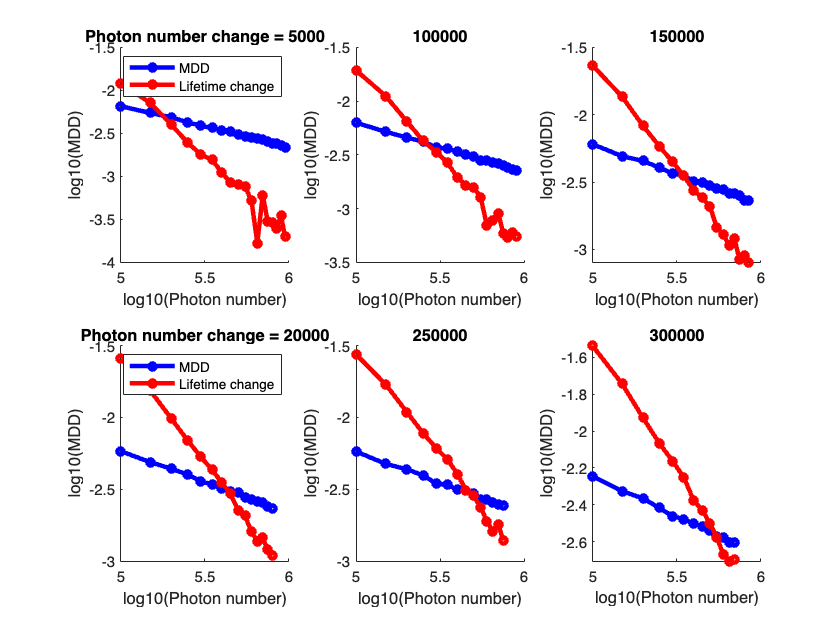

% 4. When the sensor expression level changes (sensor photon number change but
% autofluorescence remains the same), what's the minimum photon number to
% tolerate photon number change induced apparent lifetime change?

% First assume a certain amount of photon count change, at a certain p1
% condition, calculate the mean lifetime difference between two photon
% number conditions; compare this difference with minimum detectable
% difference



% tau_MDD_SS = tau_MDD_SS_5*(1.96/2.8); % use the MDD with 5 sample pairs for comparison, this MDD use 1.96 coeffcient instead of 2.8

detectable_point = zeros(1, 6); % collect the minimum photon number for each photon change conditions

changes_for_comparison_all = []; % collect the sensor expression (photon number) change induced lifetime change

for photon_change_steps = 1:6 % each photon change is 50000 number of photon change

    for i = 1:length(p1_samples) % for each p value, a seris of lifetime change with photon number change will be calculated
    
        mean_change_lft = zeros(1, length(SS_samples)-photon_change_steps); % initialize the vector for lifetime change
        mean_change_lft_std = zeros(1, length(SS_samples)-photon_change_steps);% initialize the vector for the standard deviation of lifetime change
    
        for j = 1:(length(SS_samples)-photon_change_steps) % depending on the photon change steps, there will be different number of lifetime chagne calculated
    
    
            mean_change_lft(j) = tau_mean_all(j+photon_change_steps,i) - tau_mean_all(j,i); % calculated the mean difference between two photon number conditoin
            mean_change_lft_std(j) = sqrt(tau_std_all(j+photon_change_steps,i)^2 + tau_std_all(j,i)^2); % calculated the std of difference between two photon number conditoin
        end
    
        eval(['mean_change_lft_p1_', num2str(i), '=mean_change_lft;']) % save a variable for each p1 conditon
        eval(['mean_change_lft_std_p1_', num2str(i), '=mean_change_lft_std;']) % save a variable for each p1 conditon
    end

    changes_for_comparison = abs(mean_change_lft_p1_11); % use p = 0.5 as an example, which is xxxx_11 variable
    changes_for_comparison_all = [changes_for_comparison_all; [changes_for_comparison, nan(1, 18-length(changes_for_comparison))]]; % collect those vectors for lifeitme change

    Test_detectable = changes_for_comparison - tau_MDD_SS_all{photon_change_steps}; % compare lifetime change and minimum detectable difference

    for k = 1:length(Test_detectable)
        if Test_detectable(k) < 0 % when the lifetime change is smaller than MDD
            if k == 1 % if it's already the first photon number value

                detectable_point(photon_change_steps) = 5; % define the detectable point as the first photon number simulated;
                % for I'm using the log10 value for the interpoation (next
                % step), thus here the 100000 value is defined as 5
            else
                % do linear interpolation based on the log10 values of x
                % and y axis to determine the intercept value, as the
                % minimum photon number needed
                [x_photon, y_lifetime] = polyxpoly(log10([100000+(k-2)*50000, 100000+(k-1)*50000]), log10([changes_for_comparison(k-1), changes_for_comparison(k)]), log10([100000+(k-2)*50000, 100000+(k-1)*50000]), log10([tau_MDD_SS_all{photon_change_steps}(k-1), tau_MDD_SS_all{photon_change_steps}(k)]));
                detectable_point(photon_change_steps) = x_photon;
                
            end
            
            
            break
        end
    end


    % plot the lifetime change vector and MDD vector for each photon number
    % step
    subplot(2,3,photon_change_steps)
    plot(log10(SS_samples(1:end-photon_change_steps)),log10(tau_MDD_SS_all{photon_change_steps}),'-o','MarkerSize', 4, 'LineWidth', 3, 'Color', 'b')
    xlabel('log10(Photon number)')
    ylabel('log10(MDD)')

    hold on
    
    % for i = 1:length(p1_samples)
    plot(log10(SS_samples(1:length(SS_samples)-photon_change_steps)), log10(changes_for_comparison), '-o','MarkerSize', 4,  'LineWidth', 3, 'Color', 'r')
    
    if photon_change_steps == 1 | photon_change_steps == 4
        legend({'MDD', 'Lifetime change'},'AutoUpdate','off')
        title(['Photon number change = ', num2str(photon_change_steps*5000)])
    else
        title(num2str(photon_change_steps*50000))
    end
    box off
    hold off

end

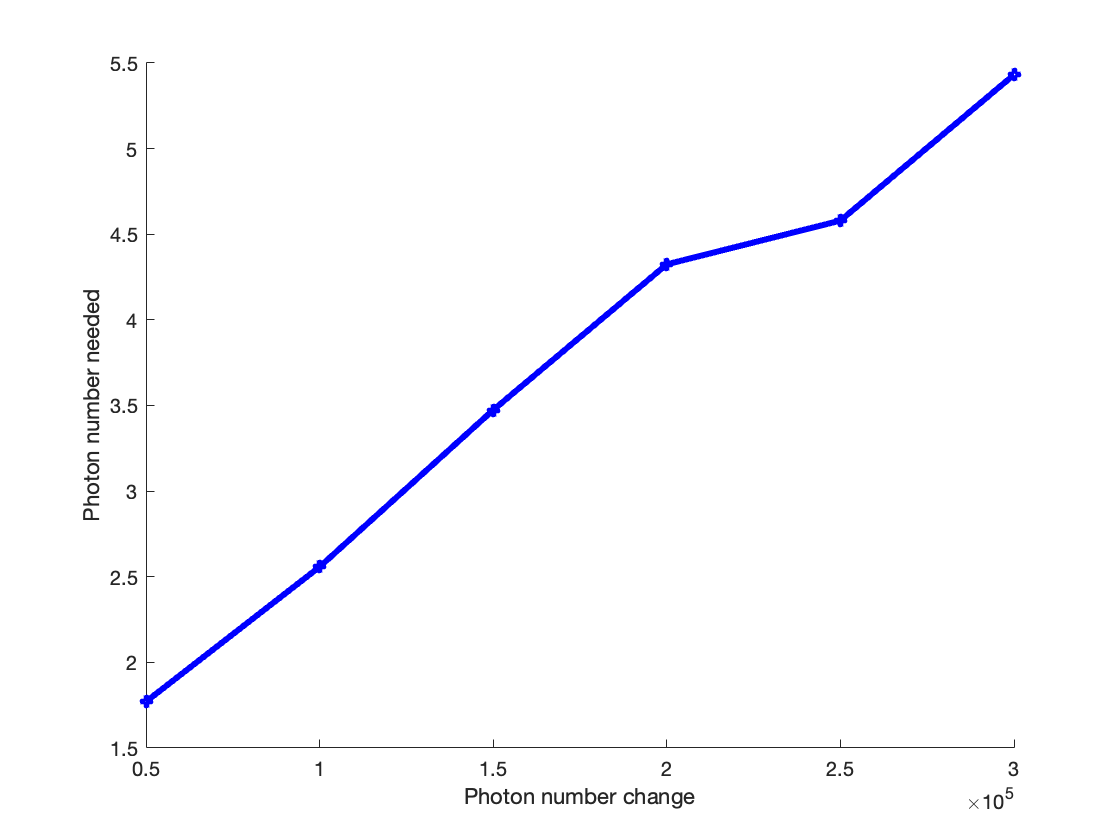


% calculated the minimum photons needed based on the log10 values
Minimum_photons_needed = (10.^detectable_point)/100000;
% plot the 
figure
plot((1:1:6)*50000, Minimum_photons_needed,'-o','MarkerSize', 4, 'LineWidth', 3, 'Color', 'b')
xlabel('Photon number change')
ylabel('Photon number needed')
box off

function [p1_fitted, tau_empTrunc, fitting_parameters] = RunFitting(sample_num, n_all)

global spc
ch = 1;

pop1 = zeros(sample_num, 1);  % population 1
pop2 = zeros(sample_num, 1);  % population 2
p1_fitted = zeros(sample_num, 1);  % fitted p1
tau_avg = zeros(sample_num, 1); % lifetime calculated based on the fitting curve calculated to infinite
tau_avgTrunc = zeros(sample_num, 1); % lifetime calculated based on the fitting curve within fitting range
tau_empTrunc = zeros(sample_num, 1); % lifetime calculated empirically based on fitting range. This will be the average lifetime I use
chi2 = zeros(sample_num, 1); % chi square from fitting
beta6 = zeros(sample_num, 1); % SHG term from fitting
backcorr = zeros(sample_num, 1); % background term from fitting

fitting_parameters = {};

for k = 1:sample_num

    spc.lifetimes{1} = n_all{1}(k,:);

    if length(n_all) > 1

        for i_components = 2:length(n_all)

            spc.lifetimes{1} = spc.lifetimes{1} + n_all{i_components}(k,:);
        end

    end


    % initiate the fitting parameters
            
    spc.fits{1}.beta1 = 10000; % p1 and p2 as 0.5
    spc.fits{1}.beta3 = 10000;
    spc.fits{1}.beta5 = 0; % Delta peak time and SHG are fixed as 0
    spc.fits{1}.beta6 = 0;

    % Running the fitting
    spc_fitexp2prfGY(ch); 

    pop1(k,1) = spc.fits{ch}.beta1;
    pop2(k,1) = spc.fits{ch}.beta3;
    p1_fitted(k,1)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3); 
    tau_avg(k,1)=spc.fits{ch}.avgTau; 
    tau_avgTrunc(k,1)=spc.fits{ch}.avgTauTrunc;
    tau_empTrunc(k,1)=spc.fits{ch}.EmpTauTrunc;
    chi2(k,1)=spc.fits{ch}.redchisq;
    beta6(k,1)=spc.fits{ch}.beta6;
    backcorr(k,1)=spc.fits{ch}.backCorr;

end

fitting_parameters{1} = tau_avg;
fitting_parameters{2} = tau_avgTrunc;
fitting_parameters{3} = chi2;
fitting_parameters{4} = beta6;
fitting_parameters{5} = backcorr;
fitting_parameters{6} = pop1;
fitting_parameters{7} = pop2;

end


function EmpLft = CalcEmpLft(range, n, channel_width)

x_axis = (1:1:(range(2)-range(1)+1))*channel_width;
EmpLft = sum(n(range(1):range(2)).*x_axis)/sum(n(range(1):range(2)));

end


function [] = FittingResults(p1_samples, SS_samples, sample_num, savename_prefix)

for i = 1:length(p1_samples) % Running fitting from each p1 conditions

    % Load simulated sensor data from saved file with different p1 condition
    p1=p1_samples(i);
    simulated_name = ['Simulated_data/', num2str(p1), '_sensor.mat'];
    load(simulated_name)

    p1_fitted = zeros(sample_num, length(SS_samples));  % fitted p1
    tau_empTrunc = zeros(sample_num, length(SS_samples)); % lifetime calculated empirically based on fitting range. This will be the average lifetime I use
    fitting_parameters = {};


    for j = 1:length(SS_samples) % Under each sample size condition
        n_all = {};

        n_all{1} = n_sensor_simulated{j};

        SS = SS_samples(j);

        FixedBackground = SS*afterpulse_ratio/251 + autofluo_bkgrd;
       
        % Load simulated background data from saved file with different sample size condition
%         bkgrd_simulated_name = ['Expression_response_all/bkgrd01_AP_0117_',num2str(SS), '.mat'];
%         load(bkgrd_simulated_name)

%         n_all{2} = n_bkgrd_all;
        n_all{2} = zeros(500, 256) + SS*afterpulse_ratio/251 + autofluo_bkgrd;

        % Load simulated autofluorescence data from saved file with different sample size condition
        SS = SS_samples(j);
        autoF_simulated_name = ['Expression_response_all/autoF_',num2str(SS), '.mat'];
        load(autoF_simulated_name)

        n_all{3} = n_auto_all;

        [p1_fitted_single, tau_empTrunc_single, fitting_parameters_single] = RunFitting(sample_num, n_all);
        p1_fitted(:,j) = p1_fitted_single;
        tau_empTrunc(:,j) = tau_empTrunc_single;
        fitting_parameters{j} = fitting_parameters_single;

    end

    % save the fitting parameters for each p1 conditon
    savename = [savename_prefix, num2str(i), '.mat'];
    save(savename, 'p1_fitted','tau_empTrunc','fitting_parameters')

end

end



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [changes_for_comparison_all, Minimum_photons_needed] = Calc_Minimum_Photons(p1_samples, SS_samples, tau_mean_all, tau_std_all, tau_MDD_SS_all)


    % 4. When the sensor expression level changes (sensor photon number change but
    % autofluorescence remains the same), what's the minimum photon number to
    % tolerate photon number change induced apparent lifetime change?
    
    % First assume a certain amount of photon count change, at a certain p1
    % condition, calculate the mean lifetime difference between two photon
    % number conditions; compare this difference with minimum detectable
    % difference
    
    % tau_MDD_SS = tau_MDD_SS_5*(1.96/2.8); % use the MDD with 5 sample pairs for comparison, this MDD use 1.96 coeffcient instead of 2.8
    
    detectable_point = zeros(1, 6); % collect the minimum photon number for each photon change conditions
    
    changes_for_comparison_all = []; % collect the sensor expression (photon number) change induced lifetime change
    
    for photon_change_steps = 1:6 % each photon change is 50000 number of photon change
    
        for i = 1:length(p1_samples) % for each p value, a seris of lifetime change with photon number change will be calculated
        
            mean_change_lft = zeros(1, length(SS_samples)-photon_change_steps); % initialize the vector for lifetime change
            mean_change_lft_std = zeros(1, length(SS_samples)-photon_change_steps);% initialize the vector for the standard deviation of lifetime change
        
            for j = 1:(length(SS_samples)-photon_change_steps) % depending on the photon change steps, there will be different number of lifetime chagne calculated
        
        
                mean_change_lft(j) = tau_mean_all(j+photon_change_steps,i) - tau_mean_all(j,i); % calculated the mean difference between two photon number conditoin
                mean_change_lft_std(j) = sqrt(tau_std_all(j+photon_change_steps,i)^2 + tau_std_all(j,i)^2); % calculated the std of difference between two photon number conditoin
            end
        
            eval(['mean_change_lft_p1_', num2str(i), '=mean_change_lft;']) % save a variable for each p1 conditon
            eval(['mean_change_lft_std_p1_', num2str(i), '=mean_change_lft_std;']) % save a variable for each p1 conditon
        end
    
        changes_for_comparison = abs(mean_change_lft_p1_11); % use p = 0.5 as an example, which is xxxx_11 variable
        changes_for_comparison_all = [changes_for_comparison_all; [changes_for_comparison, nan(1, 26-length(changes_for_comparison))]]; % collect those vectors for lifeitme change
    
        Test_detectable = changes_for_comparison - tau_MDD_SS_all{photon_change_steps}; % compare lifetime change and minimum detectable difference
    
        for k = 1:length(Test_detectable)
            if Test_detectable(k) < 0 % when the lifetime change is smaller than MDD
                if k == 1 % if it's already the first photon number value
    
                    detectable_point(photon_change_steps) = log10(SS_samples(1)); % define the detectable point as the first photon number simulated;
                    % for I'm using the log10 value for the interpoation (next
                    % step), thus here the 100000 value is defined as 5
                else
                    % do linear interpolation based on the log10 values of x
                    % and y axis to determine the intercept value, as the
                    % minimum photon number needed
                    [x_photon, y_lifetime] = polyxpoly(log10([SS_samples(1)+(k-2)*50000, SS_samples(1)+(k-1)*50000]), log10([changes_for_comparison(k-1), changes_for_comparison(k)]), log10([SS_samples(1)+(k-2)*50000, SS_samples(1)+(k-1)*50000]), log10([tau_MDD_SS_all{photon_change_steps}(k-1), tau_MDD_SS_all{photon_change_steps}(k)]));
                    detectable_point(photon_change_steps) = x_photon;
                    
                end
                
                
                break
            end
        end
    
    
        % plot the lifetime change vector and MDD vector for each photon number
        % step
        subplot(2,3,photon_change_steps)
        plot(log10(SS_samples(1:end-photon_change_steps)),log10(tau_MDD_SS_all{photon_change_steps}),'-o','MarkerSize', 4, 'LineWidth', 3, 'Color', 'b')
        xlabel('log10(Photon number)')
        ylabel('log10(MDD)')
    
        hold on
        
        % for i = 1:length(p1_samples)
        plot(log10(SS_samples(1:length(SS_samples)-photon_change_steps)), log10(changes_for_comparison), '-o','MarkerSize', 4,  'LineWidth', 3, 'Color', 'r')
        
        if photon_change_steps == 1 | photon_change_steps == 4
            legend({'MDD', 'Lifetime change'},'AutoUpdate','off')
            title(['Photon number change = ', num2str(photon_change_steps*5000)])
        else
            title(num2str(photon_change_steps*50000))
        end
        box off
        hold off
    
    end
    
    % calculated the minimum photons needed based on the log10 values
    Minimum_photons_needed = (10.^detectable_point)/100000;
    % plot the Minimum_photons_needed
    figure
    plot((1:1:6)*50000, Minimum_photons_needed,'-o','MarkerSize', 4, 'LineWidth', 3, 'Color', 'b')
    xlabel('Photon number change')
    ylabel('Photon number needed')
    box off


end





function [tau_MDD_SS_all] = Calc_MDD(p1_samples, SS_samples, n_samples, p1_plot, tau_std_all)
    tau_std_mean_SS = zeros(1, length(SS_samples)); % initializing the mean standard deviation vector
    tau_MDD_SS = zeros(1, length(SS_samples)); % initializing the minimal detectable difference vector
    
    tau_MDD_SS_all = {};
    
    for photon_change_steps = 1:6
    
        tau_MDD_SS = zeros(1, length(SS_samples) - photon_change_steps);
    
        for i = 1:length(SS_samples) - photon_change_steps
            tau_std = sqrt(tau_std_all(i, find(p1_samples == p1_plot))^2 + tau_std_all(i+photon_change_steps,find(p1_samples == p1_plot))^2);
            tau_MDD_SS(i) = tau_std*1.96/sqrt(n_samples);
        end
    
        tau_MDD_SS_all{photon_change_steps} = tau_MDD_SS;
    end

end